t = [0 0.5 1.0 1.5 2.0 2.5 3.0 3.5 4.0 5.0 6.0 6.1 7.0];
temp = [300 281 261 244 228 214 202 191 181 164 151 149 141];
scatter(t, temp)
hold on
[p,S] = polyfit(t,temp,3);
f = @(t)(p(1)*t.^3+p(2)*t.^2+p(3)*t+p(4));
p1 = plot(t,f(t),'r-');
legend(p1,'time-temp')
fprintf('九小时时的温度=%d',roundn(f(9.0),0))

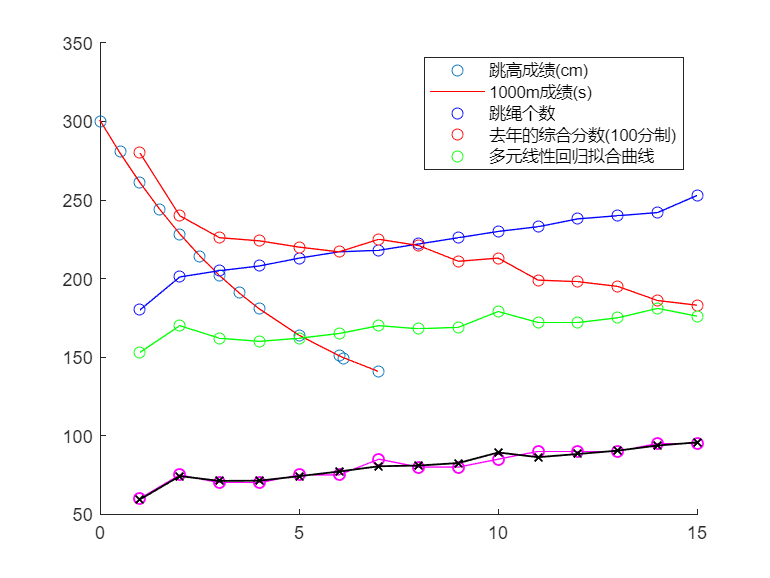

x1 = [180	201	205	208	213	217	218	222	226	230	233	238	240	242	253]';  
x2 = [280 240 226 224 220 217 225 221 211 213 199 198 195 186 183]';    
x3 = [153 170 162 160 162 165 170 168 169 179 172 172 175 181 176]';    
Y = [60	75 70 70 75	75 85 80 80	85 90 90 90	95 95]';                    

figure(1);
hold on;
plot(x1,'bo');
plot(x2,'ro');
plot(x3,'go');
plot(Y,'mo','LineWidth',1);
legend('跳高成绩(cm)','1000m成绩(s)','跳绳个数','去年的综合分数(100分制)')
len = length(Y);
pelta = ones(len,1);
x = [pelta, x1, x2, x3];

[b,bint,r,rint,stats]=regress(Y,x,0.05);

Y_NiHe = b(1) + b(2) .* x1 + b(3) .* x2 + b(4) .* x3 ;

figure(2);
hold on;
plot(x1,'bo-');
plot(x2,'ro-');
plot(x3,'go-');
plot(Y,'mo-');
plot(Y_NiHe,'kx-','LineWidth',1);
legend('跳高成绩(cm)','1000m成绩(s)','跳绳个数','去年的综合分数(100分制)','多元线性回归拟合曲线')

R_2 = 1 - sum( (Y_NiHe - Y).^2 )./ sum( (Y - mean(Y)).^2 );
str = num2str(R_2);
disp(['拟合优度为：',str])

拟合优度为：0.94903
